clc


**DH convention**

%Dimensions
L1 = 145;
L2 = 106.3;
L3 = 106.3;
L4 = 89.7;

%DH parameters
a = [0;L2;L3;L4];
alpha = [90;0;0;0] * pi/180;
d = [L1;0;0;0];
theta = [0;0;0;0];
sigma = zeros(4,1);
offset = [0;90;-90;0]* pi/180;

%Serial Link creation
DH_params = [theta d a alpha sigma offset];
Phantom = SerialLink(DH_params)

 
Phantom = 
 
noname (4 axis, RRRR, stdDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        145|          0|      1.571|          0|
|  2|         q2|          0|      106.3|          0|      1.571|
|  3|         q3|          0|      106.3|          0|     -1.571|
|  4|         q4|          0|       89.7|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1          

Phantom.name = "PhantomX";
q = [40 -30 20 20]*pi/180;
pose = Phantom.fkine(q)

pose =     0.7544   -0.1330    0.6428  188.5789
    0.6330   -0.1116   -0.7660  158.2365
    0.1736    0.9848    0.0000  234.1759
         0         0         0    1.0000


figure(1)
%Phantom.plot(q,'workspace',[-100 100 -100 100 0 500],'nobase','notiles')

**Inverse Kinematics**

desiredPos = pose(1:3,4) 

desiredPos =   188.5789
  158.2365
  234.1759


desiredOrientation = pose(1:3,1:3)

desiredOrientation =     0.7544   -0.1330    0.6428
    0.6330   -0.1116   -0.7660
    0.1736    0.9848    0.0000


approach = pose(1:3)'

approach =     0.7544
    0.6330
    0.1736


theta1 = atan2(desiredPos(2),desiredPos(1));
rad2deg(theta1)

ans = 40.0000

wristPos = desiredPos -  L4*approach

wristPos =   120.9087
  101.4544
  218.5997


**Double-pendulum inverse kinematics**

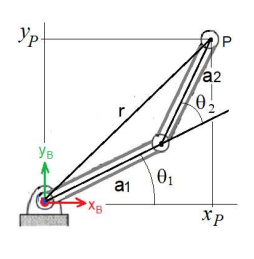

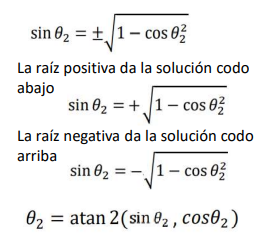

#### Caso codo arriba

#### Caso codo abajo

H01 = Phantom.A(1,theta1);
R10 = H01(1:3,1:3)';
t10 = -R10*H01(1:3,4);
H10 = [R10 t10;zeros(1,3) 1]

H10 =     0.7660    0.6428         0         0
   -0.0000    0.0000    1.0000 -145.0000
    0.6428   -0.7660    0.0000   -0.0000
         0         0         0    1.0000


wristPos_1 =  H10*[wristPos;1] 

wristPos_1 =   157.8351
   73.5997
    0.0000
    1.0000



cos_theta3 = (norm(wristPos_1(1:2))^2 - L2^2 - L3^2)/(2*L2*L3);
sin_theta3 = sqrt(1-cos_theta3^2);

theta3 = [atan2(sin_theta3,cos_theta3);atan2(-sin_theta3,cos_theta3)]

theta3 =     1.2217
   -1.2217


Se elige la configuarción codo abajo.

theta3 = theta3(2)

theta3 = -1.2217

rad2deg(theta3)

ans = -70.0000

k1 = L2+L3*cos(theta3);
k2 = L3*sin(theta3);
theta2 = atan2(wristPos_1(2),wristPos_1(1))-atan2(k2,k1)

theta2 = 1.0472

rad2deg(theta2)

ans = 60.0000

approach_1 = R10*approach

approach_1 =     0.9848
    0.1736
    0.0000


phi = atan2(approach_1(2),approach_1(1))

phi = 0.1745

theta4 = phi - theta2 - theta3;
rad2deg(theta4)

ans = 20.0000

theta = rad2deg([theta1 (theta2-pi/2) (theta3+pi/2) theta4])

theta =    40.0000  -30.0000   20.0000   20.0000


**Confirmation**

Q = Phantom.ikine(pose,deg2rad([0 0 0 0]),[1 1 1 0 0 0])

Q =     0.6981   -0.5008    0.3956    0.1844


rad2deg(Q)

ans =    40.0000  -28.6962   22.6668   10.5678


function PlotRobot(Robot,q)
figure()
Robot.plot(q,'nobase','notiles')
zlim([0 5])
end